## Analysis of RLC circuits 

This assignment involves the analysis of a series RLC circuit. You will derive ttransfer function, and analyze the system's response to various inputs. 

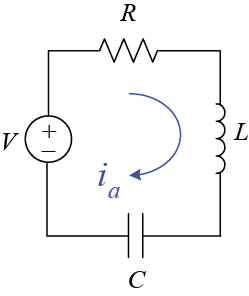

The operation of the circuit can be described by the following **governing equation**


$$
V(t) - R i - L \frac{di}{dt} - \frac{1}{C} \int i dt = 0
$$


For details on derivation of the above differential equation, refer to [RLC_circuits_background](matlab:open('/MATLAB Drive/EE231_Auto_Cntrl_Th/Assignment2/RLC_circuits_background.mlx')). 

### Derivation of the Transfer Function

The first step in analyzing a control system is often to derive its transfer function, which describes how the output of the system responds to an input over time. 

Use the properties of Laplace transform and derive the transfer function $G(s) = \frac{I(s)}{V(s)}$ from the voltate tot he current signals. Express the transfer function symbolically using symbols $R$, $L$ and $C$. 

**Enter your derivation here (show your steps)**

Taking Laplace transform on both sides of the above equation: 


$$ V(s) - RI(s) - LsI(s) - \frac{1}{CS}I(s) = 0 $$


Factoring the coefficients of $I(s)$ and rearranging: 


$$\frac{I(s)}{V(s)} = \frac{s}{Ls^2 + Rs + 1/C} $$


### Numerical Computation of Impulse and Step Responses

Understanding how a system responds to basic inputs like impulse and step functions is crucial for dynamical system analysis. These responses provide insight into the system's stability and transient behavior.

Given an RLC circuit with $R = 10 \Omega$, $L = 0.5 H$, $C=0.01F$, create a system object G using the `tf` function. 

%enter your code to create G here 
R = 10; L = 0.5; C=0.01; 
G = tf([1,0], [L,R,1/C])

G =
 
           s
  --------------------
  0.5 s^2 + 10 s + 100
 
Continuous-time transfer function.
Model Properties


Numerically compute the impulse and step responses for 2s of the RLC circuit using the system object created above. Plot the responses and briefly discuss the system's behavior observed from these plots.

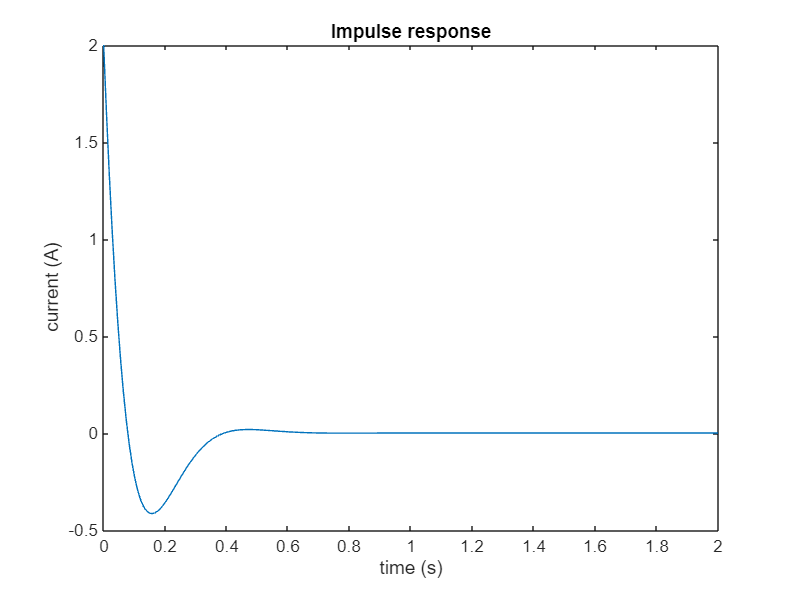

%enter your code to compute and plot impulse and step responses here 
[iImpulse,tImpulse] = impulse(G,2);
plot(tImpulse, iImpulse)
ylabel('current (A)')
xlabel('time (s)')
title('Impulse response')

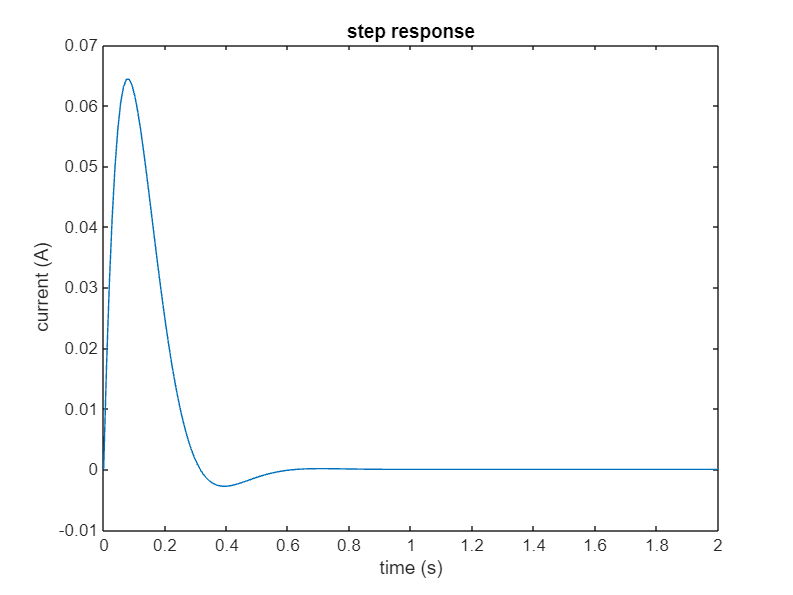

[iStep, tStep] = step(G,2);
plot(tStep,iStep); 
xlabel('time (s)')
ylabel('current (A)')
title('step response') 

**Provide your discussion here: **

Observations: 

- In both cases, the steady state current is zero. This is reflects the fact there is a capacitor in series which acts like a open circuit for DC. Therefore, there cannot be any current in steady state. 

- In the step resonse behavior, note that even thought the voltage across the circuit changed suddently (discontinuous), the current is changing smoothly (continuous). This is because inductors don't allow sudden changes in current. 

- In both cases, we see some oscillatory behavior which are damped out over time. 

### Analytical Computation of Impulse and Step Responses

 Besides numerical methods, analytical solutions to impulse and step responses offer a deeper understanding of the system's dynamics.

Analytically compute the impulse and step responses of the RLC circuit. Use MATLAB's symbolic computation capabilities for this task.

%enter your code for analytical computation of impulse and step responses
%here
syms R C L postive 
syms s t v(t) i(t) Gsym(s)

%impulse response 
v(t) = dirac(t); 
V(s) = laplace(v);
Gsym(s) = s/(L*s^2 + R*s + (1/C));
I(s) = Gsym(s)*V(s);
i(t) = ilaplace(I);
iImpulseAnalyticalFun = matlabFunction(i);

%step response 
v(t) = heaviside(t); 
V(s) = laplace(v);
I(s) = Gsym(s)*V(s);
i(t) = ilaplace(I);
iStepAnalyticalFun = matlabFunction(i);

Compare the analytical and numerical impulse response in a plot. 

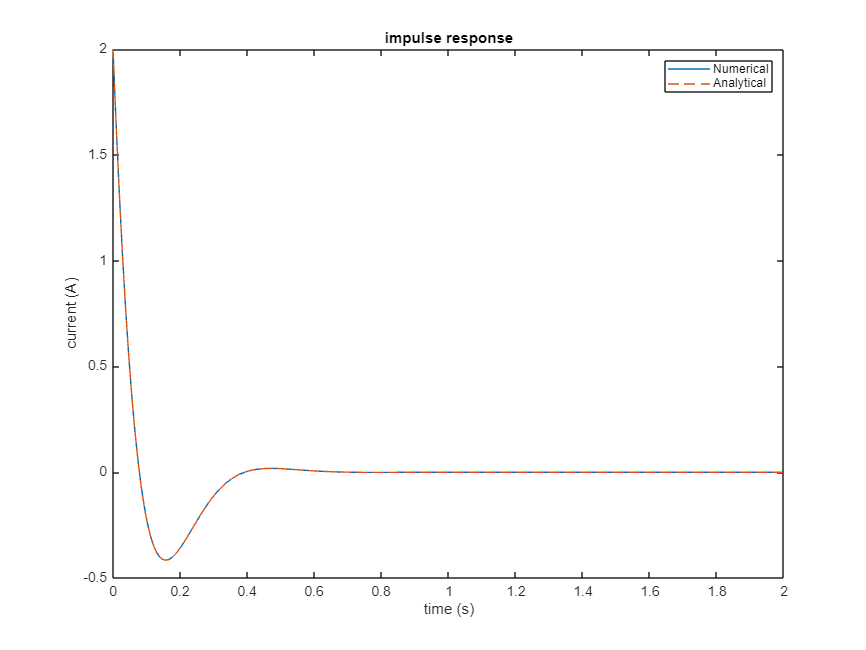

%enter your code here 
R = 10; L = 0.5; C=0.01; 
iImpulseAnalytical = iImpulseAnalyticalFun(tImpulse,C,L,R);
plot(tImpulse, iImpulse, tImpulse, iImpulseAnalytical, '--'); 
legend('Numerical', 'Analytical')
xlabel('time (s)') 
ylabel('current (A)') 
title('impulse response') 

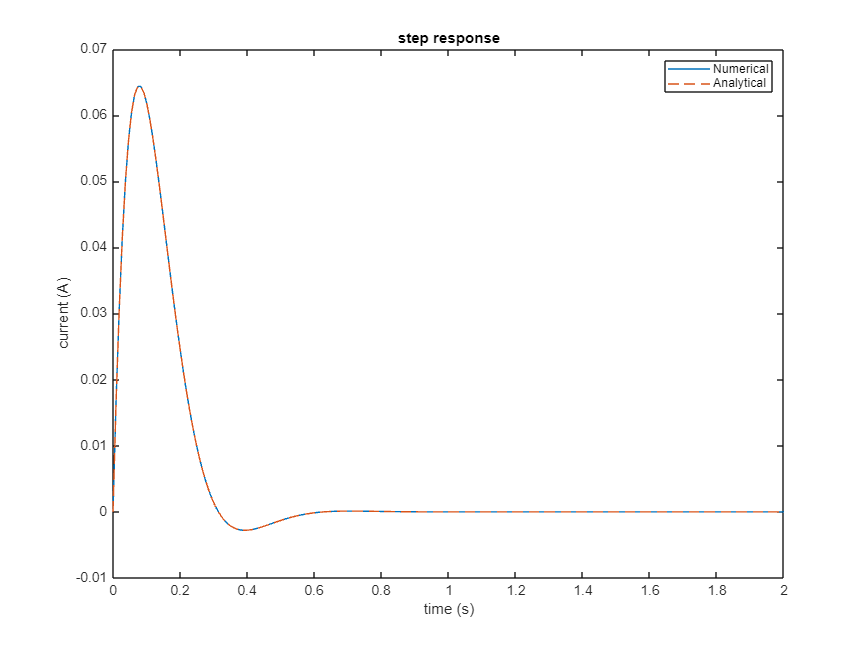



iStepAnalytical = iStepAnalyticalFun(tStep,C,L,R);
plot(tStep, iStep, tStep, iStepAnalytical, '--'); 
legend('Numerical', 'Analytical')
xlabel('time (s)') 
ylabel('current (A)') 
title('step response') 

### Analysis of Sinusoidal Inputs

The response of a system to sinusoidal inputs at various frequencies can reveal its filtering characteristics, including pass bands and stop bands.

 For the RLC circuit, numerically compute the output for three sinusoidal inputs 

- 1$Hz$ 

- 50$Hz$ 

- 500$Hz$

The amplitudes for all three input sinusoidal signals must remain same. 

Plot all three responses for 4s in a single figure. 

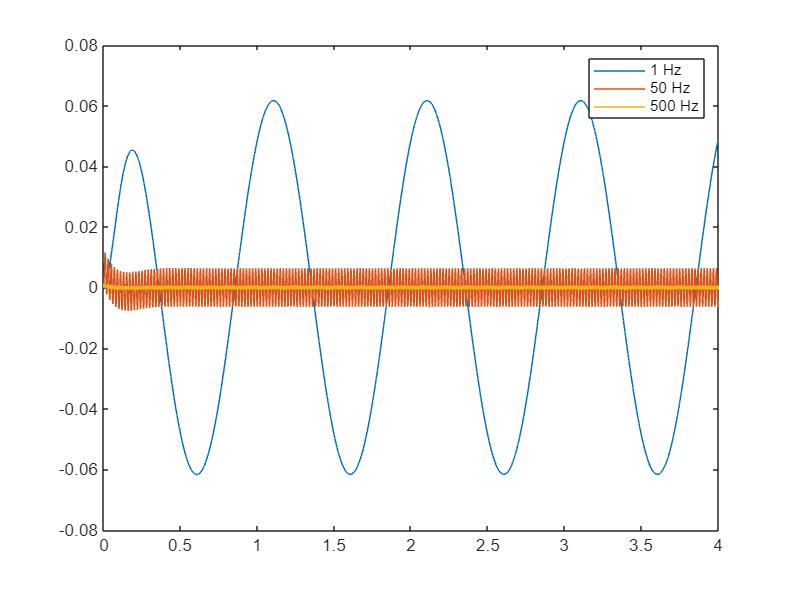

% enter your code here 
tForced = linspace(0,4,100000); 
f1 = 1; f2 = 50; f3 = 500; 
s1 = sin(2*pi*f1*tForced); s2 = sin(2*pi*f2*tForced); s3 = sin(2*pi*f3*tForced); 
response1 = lsim(G,s1,tForced); response2 = lsim(G,s2,tForced); response3 = lsim(G,s3,tForced); 
plot(tForced,response1, tForced, response2, tForced, response3); 
legend('1 Hz', '50 Hz', '500 Hz')

### Submission instructions

After completing all the sections, export your version of this script as a .pdf file and submit it in Canvas. 